Consider a clamped-pinned beam modelled by von Karman beam theory.

clear all; clc

## Model Setup

Building FE model
Assembling M,C,K matrices
Applying boundary conditions
Solving undamped eigenvalue problem


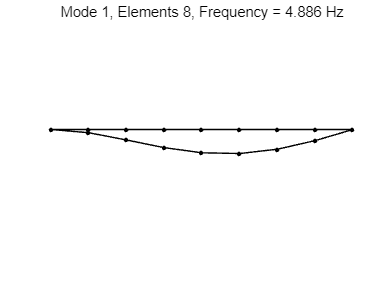

Getting nonlinearity coefficients
Assembling Tensors
Assembling external force vector


nElements = 8;
kappa = 1e5; % strong damping
[M,C,K,fnl,~,outdof] = build_model(nElements,kappa);

n = length(M);

### Dynamical System Setup

DS = DynamicalSystem();
set(DS,'M',M,'C',C,'K',K,'fnl',fnl);
set(DS.Options,'Emax',11,'Nmax',10,'notation','multiindex','outDOF',outdof)

**Add external forcing and also control matrix**

Bext     = zeros(n,1); Bext(outdof(2),1)=1; 
ExtForce = @(t) Bext*sin(20*t+15*t/(2+sin(t)));

% ExtForce = @(t) Bext*sin(20*t+15*t/(2+sin(t))) * 0;
epsilon  = 50;
% epsilon  = 1;
set(DS,'D',Bext,'E',ExtForce,'epsilon',epsilon);

### Linear Modal analysis

[V,D,W] = DS.linear_spectral_analysis();

Due to high-dimensionality, we compute only the first 11 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 3.411040e-02
modal damping ratio for 2 mode is 1.105810e-01
modal damping ratio for 3 mode is 2.310303e-01
modal damping ratio for 4 mode is 3.963511e-01
modal damping ratio for 5 mode is 6.084896e-01
modal damping ratio for 6 mode is 8.705050e-01
modal damping ratio for 7 mode is 1.182038e+00
modal damping ratio for 8 mode is 1.644161e+00
modal damping ratio for 9 mode is 2.089910e+00
modal damping ratio for 10 mode is 2.665776e+00
modal damping ratio for 11 mode is 3.373412e+00

 The first 22 nonzero eigenvalues are given as 
   1.0e+04 *
  -0.0001 + 0.0031i
  -0.0001 - 0.0031i
  -0.0011 + 0.0099i
  -0.0011 - 0.0099i
  -0.0048 + 0.0202i
  -0.0048 - 0.0202i
  -0.0141 + 0.0328i
  -0.0141 - 0.0328i
  -0.0333 + 0.0435i
  -0.0333 - 0.04

## SSM Reduced dynamics 

S = SSM(DS);
set(S.Options, 'reltol', 0.1,'notation','multiindex')
order = 5;

**Reduced dynamics simulation**

*Construction of initial condition*

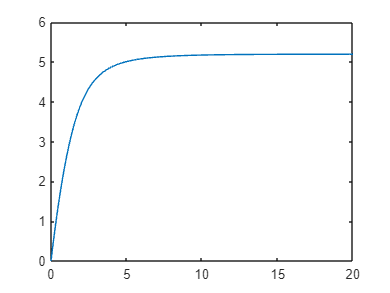

om = 2*pi/20;
nsteps = 500;
DSstatic = DynamicalSystem();
set(DSstatic,'M',M,'C',1000*C,'K',K,'fnl',fnl);
set(DSstatic.Options,'HarmonicForce',false);
fmidspan = zeros(n,1);
fmidspan(outdof(2)) = 1500;
Fmidspan = @(t) fmidspan;
set(DSstatic,'fext',Fmidspan);
[ts, xs, xf] = time_integration_transient(DSstatic,om,'nCycles',...
    1, 'nSteps', nsteps,...
    'integrationMethod','ode15s','outdof',outdof,'init',zeros(2*n,1));
figure;
plot(ts,xs(:,2))


% master subspace
modes = [1 2 3 4];
S.choose_E(modes);

No (near) outer resonances detected in the (truncated) spectrum
sigma_out = 19121
(near) inner resonance detected for the following combination of master eigenvalues
     2     1     0     0
     1     2     0     0
     1     1     1     0
     1     1     0     1
These are in resonance with the follwing eigenvalues of the master subspace
  -1.0472 +30.6815i
  -1.0472 -30.6815i
 -11.0053 +98.9126i
 -11.0053 -98.9126i
sigma_in = 19121


% compute autonomous SSM coefficients
[W_0,R_0] = S.compute_whisker(order);

Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 7.63E-02 MB
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 1.84E-01 MB
Manifold computation time at order 4 = 00:00:00
Estimated memory usage at order  4 = 2.97E-01 MB
Manifold computation time at order 5 = 00:00:00
Estimated memory usage at order  5 = 5.57E-01 MB


% construct initial condition
z0 = xf';

auData = construct_autoData(DS, modes, R_0);
cont   = struct();
cont.Q    = blkdiag(0.1*eye(n),zeros(n));
cont.Q    = blkdiag(0.1*eye(n),zeros(n));
cont.Rhat = 0.01;
cont.Mhat = eye(2*n)*0;
% cont.zd   = 0;

% cont.Q    = 100*blkdiag(0.1*eye(n),zeros(n));
% cont.Rhat = 0.001;
% cont.Mhat = eye(2*n)*0;
% cont.zd   = 0;

% first segment
t0 = 0; t1 = 0.2;
tspan = linspace(t0,t1,nsteps);
om = 2*pi/t1;
set(DS,'u',[]);
[tfullwo, xfullwo] = time_integration_transient(DS,om,'nCycles',...
    1, 'nSteps', nsteps,...
    'integrationMethod','ode15s','outdof',outdof,'init',z0,'ts',0);

## Cut-off Criteria

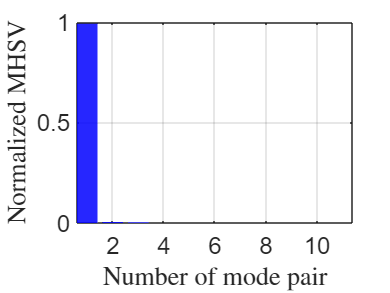

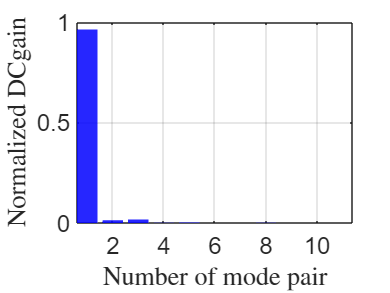

MHSV sum of the first 2 pair
    0.9963
DCgain sum of the first 2 pair
    0.9773


res = Cutof_LQR_closed_loop_MT2_comp(DS,11);

#### **1 Segment - closed loop**

% traj_closed1 = LQR_closed_loop(DS,z0,'linear',tspan,auData,W_0,modes,1:2,cont);
traj_closed1 = LQR_closed_loop(DS,z0,'nonlinear',tspan,auData,W_0,modes,1:2,cont);

pl
  -1.1855 + 0.0405i
  -1.1855 - 0.0405i
  -0.0687 + 0.0076i
  -0.0687 - 0.0076i
Call fminunc to find the projection of point on SSM
approx error
   7.2732e+03
approx error
   7.2732e+03
approx error
   7.2732e+03
approx error
   7.2732e+03
approx error
   7.2732e+03
approx error
   1.4809e+05
approx error
   1.4809e+05
approx error
   1.4809e+05
approx error
   1.4809e+05
approx error
   1.4809e+05
approx error
   1.7077e+03
approx error
   1.7077e+03
approx error
   1.7077e+03
approx error
   1.7077e+03
approx error
   1.7077e+03
approx error
  205.1117
approx error
  205.1117
approx error
  205.1117
approx error
  205.1116
approx error
  205.1120
approx error
    2.9652
approx error
    2.9652
approx error
    2.9652
approx error
    2.9652
approx error
    2.9652
approx error
    2.8004
approx error
    2.8004
approx error
    2.8004
approx error
    2.8004
approx error
    2.8004
approx error
    2.7687
approx error
    2.7687
approx error
    2.7687
approx error
    2.7687
appr

% full dynamic
om = 2*pi/t1;
ufun = @(t) transpose(interp1(traj_closed1.time,traj_closed1.ut',t,'linear','extrap'));
set(DS,'u',ufun);
[tfullwc, xfullwc] = time_integration_transient(DS,om,'nCycles',...
    1, 'nSteps', nsteps,...
    'integrationMethod','Newmark','outdof',outdof,'init',z0);

Iteration 0, Residual norm = 0.99824
Iteration 1, Residual norm = 4.612e-06
time integration completed: 0.2%
Iteration 0, Residual norm = 0.97611
Iteration 1, Residual norm = 1.2075e-05
time integration completed: 0.4%
Iteration 0, Residual norm = 0.9911
Iteration 1, Residual norm = 3.5443e-06
time integration completed: 0.6%
Iteration 0, Residual norm = 0.89404
Iteration 1, Residual norm = 5.8953e-06
time integration completed: 0.8%
Iteration 0, Residual norm = 0.98008
Iteration 1, Residual norm = 2.8789e-06
time integration completed: 1%
Iteration 0, Residual norm = 0.79555
Iteration 1, Residual norm = 3.1707e-06
time integration completed: 1.2%
Iteration 0, Residual norm = 0.96882
Iteration 1, Residual norm = 2.4089e-06
time integration completed: 1.4%
Iteration 0, Residual norm = 0.70168
Iteration 1, Residual norm = 1.9457e-06
time integration completed: 1.6%
Iteration 0, Residual norm = 0.95593
Iteration 1, Residual norm = 2.0566e-06
time integration completed: 1.8%
Iteration 0, R

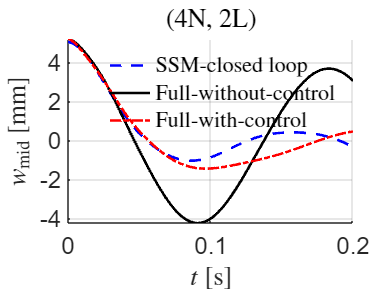


figure; hold on
plot(traj_closed1.time, traj_closed1.zt(2,:),'b--','DisplayName','SSM-closed loop','LineWidth',2);

plot(tfullwo, xfullwo(:,2),'k-','DisplayName','Full-without-control','LineWidth',2);
plot(tfullwc, xfullwc(:,2),'r-.','DisplayName','Full-with-control','LineWidth',2);
xlabel('$t$ [s]','Interpreter',"latex")
ylabel('$w_\mathrm{mid}$ [mm]','Interpreter','latex');
title('(4N, 2L)','Interpreter','latex')

set(gca,'FontSize',18);
grid on, axis tight
legend('show','Interpreter','latex'); legend boxoff
set(gca,'FontSize',18); grid on, axis tight

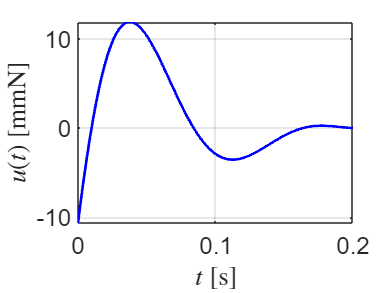



figure;
plot(traj_closed1.time,traj_closed1.ut(1,:),'b-','LineWidth',2); hold on
xlabel('$t$ [s]','Interpreter',"latex")
ylabel('$u(t)$ [mmN]','Interpreter','latex')

set(gca,'FontSize',18); grid on, axis tight

uz = traj_closed1.ut;
time = traj_closed1.time;
save("uz.mat","uz")
save("time.mat",'time')

#### 2 Segments** - closed loop**


t0 = 0; t1 = 0.1;
tspan3 = linspace(t0,t1,nsteps);
traj3 = LQR_closed_loop(DS,z0,'linear',tspan3,auData,W_0,modes,1:2,cont);

pl
  -1.1855 + 0.0405i
  -1.1855 - 0.0405i
  -0.0687 + 0.0076i
  -0.0687 - 0.0076i
p0
  -1.1855 + 0.0405i
  -1.1855 - 0.0405i
  -0.0687 + 0.0076i
  -0.0687 - 0.0076i
历时 0.031839 秒。
历时 0.028975 秒。
Time for backward simulation of Riccati ODE is 2.927870e-02
历时 0.035040 秒。
Time for backward simulation of compensated ODE is 3.702610e-02
历时 0.026113 秒。
Time for forward simulation of ODEs for modal coordinates is 2.769800e-02


ufun3 = @(t) transpose(interp1(traj3.time,traj3.ut',t,'linear','extrap'));
set(DS,'u',ufun3);
[tfull3, xfull3,x3f,xt3] = time_integration_transient(DS,2*pi/(t1-t0),'nCycles',...
    1, 'nSteps', nsteps,...
    'integrationMethod','ode15s','outdof',outdof,'init',z0);

t2 = 0.2;
tspan4 = linspace(t1,t2,nsteps);
traj4  = LQR_closed_loop(DS,x3f','linear',tspan4,auData,W_0,modes,1:2,cont);

pl
   0.4353 + 0.1408i
   0.4353 - 0.1408i
   0.0213 + 0.0157i
   0.0213 - 0.0157i
p0
   0.4353 + 0.1408i
   0.4353 - 0.1408i
   0.0213 + 0.0157i
   0.0213 - 0.0157i
历时 0.024397 秒。
历时 0.007923 秒。
Time for backward simulation of Riccati ODE is 8.150500e-03
历时 0.020716 秒。
Time for backward simulation of compensated ODE is 2.123860e-02
历时 0.012061 秒。
Time for forward simulation of ODEs for modal coordinates is 1.268440e-02


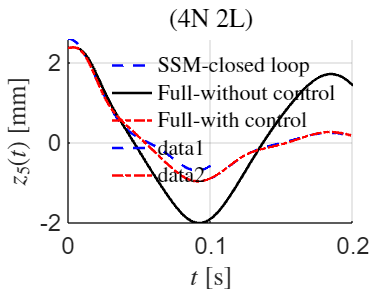


ufun4 = @(t) transpose(interp1(traj4.time,traj4.ut',t,'linear','extrap'));
set(DS,'u',ufun4);
[tfull4, xfull4,x4f,xt4] = time_integration_transient(DS,2*pi/(t2-t1),'nCycles',...
    1, 'nSteps', nsteps,...
    'integrationMethod','ode15s','outdof',outdof,'init',x3f','ts',t1);
% outdof 5
figure; hold on
plot(traj3.time, traj3.zt(1,:),'b--','DisplayName','SSM-closed loop','LineWidth',2);
% plot(traj3.time, traj3.zt_auto(1,:),'b-','DisplayName','W(p)');
plot(tfullwo, xfullwo(:,1),'k-','DisplayName', 'Full-without control','LineWidth',2);
plot(tfull3, xfull3(:,1),'r-.','DisplayName', 'Full-with control','LineWidth',2);
plot(traj4.time, traj4.zt(1,:),'b--','LineWidth',2);
% plot(traj4.time, traj4.zt_auto(1,:),'b-');
plot(tfull4, xfull4(:,1),'r-.','LineWidth',2);
legend('show','Interpreter','latex'); legend boxoff
xlabel('$t$ [s]','Interpreter',"latex")
zk = strcat('$z_{',num2str(outdof(1)),'}(t)$ [mm]');
ylabel(zk,'Interpreter','latex');
title('(4N 2L)','Interpreter','latex')
set(gca,'FontSize',18);
grid on, axis tight

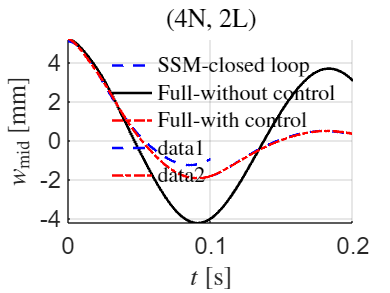


% outdof 11
figure; hold on
plot(traj3.time, traj3.zt(2,:),'b--','DisplayName','SSM-closed loop','LineWidth',2);
% plot(traj3.time, traj3.zt_auto(1,:),'b-','DisplayName','W(p)');
plot(tfullwo, xfullwo(:,2),'k-','DisplayName', 'Full-without control','LineWidth',2);
plot(tfull3, xfull3(:,2),'r-.','DisplayName', 'Full-with control','LineWidth',2);
plot(traj4.time, traj4.zt(2,:),'b--','LineWidth',2);
% plot(traj4.time, traj4.zt_auto(1,:),'b-');
plot(tfull4, xfull4(:,2),'r-.','LineWidth',2);
legend('show','Interpreter','latex'); legend boxoff
xlabel('$t$ [s]','Interpreter',"latex")
% zk = strcat('$z_{',num2str(outdof(2)),'}(t)$');
% ylabel(zk,'Interpreter','latex');
ylabel('$w_\mathrm{mid}$ [mm]','Interpreter','latex');
title('(4N, 2L)', 'Interpreter','latex')
set(gca,'FontSize',18);
grid on, axis tight

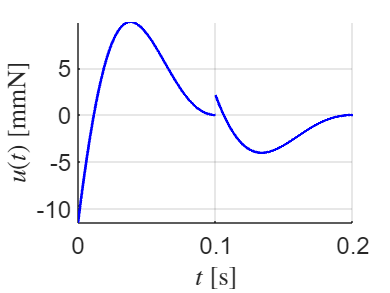


figure;
hold on
plot(traj3.time,traj3.ut(1,:),'b-','LineWidth',2); 
plot(traj4.time,traj4.ut(1,:),'b-','LineWidth',2);

xlabel('$t$ [s]','Interpreter',"latex")
ylabel('$u(t)$ [mmN]','Interpreter','latex')

set(gca,'FontSize',18); grid on, axis tight

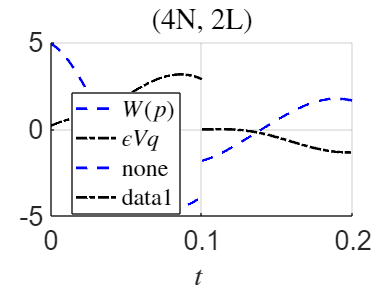

figure; hold on
tt = [traj3.time, traj4.time];
zt = [traj3.zt, traj4.zt];
zauto = [traj3.zt_auto, traj4.zt_auto];
ep_Vq = zt - zauto;

plot(traj3.time, traj3.zt_auto(2,:),'b--','DisplayName','$W(p)$','LineWidth',2);
plot(traj3.time, traj3.zt(2,:)-traj3.zt_auto(2,:),'k-.','DisplayName','$\epsilon Vq$','LineWidth',2);

plot(traj4.time, traj4.zt_auto(2,:),'b--','DisplayName','none','LineWidth',2);
plot(traj4.time, traj4.zt(2,:)-traj4.zt_auto(2,:),'k-.','LineWidth',2);

legend('show','Interpreter',"latex",'Location','best');
xlabel('$t$ ','Interpreter',"latex")
% zk = strcat('$z_{',num2str(outdof(1)),'}(t)$');
% ylabel(zk,'Interpreter','latex');
title('(4N, 2L)', 'Interpreter','latex')
set(gca,'FontSize',20);
grid on
% axis tight

print(gcf, 'Beam_z(t)_Factorization.png', '-dpng','-r300');

## Vibration video

% 
% vt  =  [xt3; xt4];
% n   = size(vt,1);
% % 
% % hfig = figure;
% % hold on;
% % for i = 1:n
% %     clf;
% %     Draw(nElements,kappa,vt(i,:));
% %     saveas(gcf, ['frame' num2str(i, '%03d') '.png']);
% %     drawnow
% %     close(gcf)
% % end
% 
% % Hermite interpolation
% tt     = [tfull3; tfull4];
% output     = [xt3; xt4];
% n      = length(tt);
% li0    = linspace(0,2.7,9); 
% delta_l = output(:,[1,4,7,10,13,16,19]);
% xt      = [zeros(n,1),delta_l,zeros(n,1)] + li0;
% xt      = xt .* 1000; % m to mm
% zt      = [zeros(n,1),output(:,[2,5,8,11,14,17,20]),zeros(n,1)];
% theta_t = [zeros(n,1), output(:,[3,6,9,12,15,18,21,22])];
% z_prime = tan(theta_t);
% % x_val   = linspace(0,2700,100);
% interp_num = 25;
% total_num  = interp_num * nElements;
% % hFig = figure('Position', [0, 0, 800, 400]);
% % hold on;
% % xticks(0:300:2700)
% % yticks(-2:1.0:6)
% % xlim([0,2700])
% % ylim([-2,6])
% % xlabel("x/mm")
% % ylabel("z/mm")
% % box on;  % 显示所有坐标轴
% % hFig.DataAspectRatioMode = 'manual';  % 设置比例模式为手动
% % hFig.DataAspectRatio = [1 1.1 factor];  % 设置x轴、y轴和z轴的比例
% x_save = zeros(total_num,n);
% z_save = zeros(total_num,n);
% 
% for i = 1:n
%     x_val      = zeros(total_num,1);
%     z_val      = zeros(total_num,1);
%     for k = 1:nElements 
%         [A,b] = Ab_form(xt(i,k:k+1),zt(i,k:k+1),z_prime(i,k:k+1));
%         a_4   =  Gram_Schmidt(A,b');
%         x_val((k-1)*interp_num+1 : k*interp_num) = linspace(xt(i,k), xt(i,k+1),interp_num);
%         z_val((k-1)*interp_num+1 : k*interp_num) = HerFunc(a_4, x_val((k-1)*interp_num+1 : k*interp_num));
%     end
%     x_save(:,i) = x_val;
%     z_save(:,i) = z_val;
%     % z_interpolated = interp1(xt(i,:), [zt(i,:), z_prime(i,:)], x_val, 'spline', 'extrap');
%     % beamDisplacement = plot(x_val, z_val, 'b-');
%     % beamsca = scatter(xt(i,:), zt(i,:), 'ko');
%     % drawnow
%     % frame = getframe(gcf);
%     % imwrite(frame.cdata, ['frame' num2str(i, '%03d') '.png']);
%     % delete(beamDisplacement);
%     % delete(beamsca)
% end
% close(hFig)
% 
% % 初始化 figure
% hFig = figure;
% 
% % 添加梁的基线
% beamBaseline = plot(0, 'k-');
% hold on;
% xlim([0,2700])
% ylim([-2,5.2])
% % 动画循环
% for i = 1:n
%     % 绘制当前时间点的位移
%     beamDisplacement = plot(xt(i,:), zt(i,:), 'bo-');
% 
%     % 更新标题，显示当前时间
%     % title(['Time = ', num2str(tt(i))]);
% 
%     % 可选：添加坐标轴标签等
%     xlabel('x/mm');
%     ylabel('z/mm');
% 
%     % 暂停一段时间以控制动画速度
%     % pause(0.0001);
%     drawnow
%     % 保存每一帧，如果需要创建 GIF
%     % frame = getframe(gcf);
%     frame = getframe(gcf);
%     imwrite(frame.cdata, ['frame' num2str(i, '%03d') '.png']);
%     % print(gcf, ['frame' num2str(i, '%03d') '.png'], '-dpng');
%     % 清除之前的位移图形
%     delete(beamDisplacement);
% end
% 
% 
% 
% % 关闭 figure
% % close(hFig);
% 
% pngFiles = dir('*.png');
% % Read all PNG images
% numImages = numel(pngFiles);
% frames = cell(1, numImages);
% 
% for i = 1:numImages
%     frames{i} = imread(pngFiles(i).name);
%     % frames{i} = imresize(frames{i}, [656, 875]);
% end
% 
% % Create a video
% outputVideo = VideoWriter('output.avi');
% open(outputVideo);
% 
% for i = 1:numImages
%     writeVideo(outputVideo, frames{i});
% end
% 
% close(outputVideo);


% clear all
% clc
% 
% % 3D Beam
% load("x_save.mat","x_save")
% load("z_save.mat","z_save")
% 
% load("tfull3.mat","tfull3")
% load("tfull4.mat","tfull4")
% load("xfull3.mat","xfull3")
% load("xfull4.mat","xfull4")
% load("traj3.mat","traj3")
% load("traj4.mat","traj4")
% 
% load("tfullwo.mat","tfullwo")
% load("xfullwo.mat","xfullwo")
% 
% h=14;                                   %Height of beam [mm]
% b=14; 
% facesHead = [1 2 3 4;...
%              1 2 6 5;...
%              4 3 7 8;...
%              1 5 8 4;...
%              2 6 7 3];
% 
% facesTail = [1 2 6 5;...
%              4 3 7 8;...
%              1 5 8 4;...
%              2 6 7 3];
% 
% facesBody = [1 2 6 5;...
%              4 3 7 8;...
%              1 5 8 4;...
%              2 6 7 3];
% 
% faces = [1 2 3 4;...
%          5 6 7 8;...
%          1 2 6 5;...
%          4 3 7 8;...
%          1 5 8 4;...
%          2 6 7 3];
% patchcolor = '#F08918';
% patchcolor2 = [1, 0.54, 0.094];
% % linecolor  = [1, 0.4, 0.00];
% linecolor  = [0.1, 0.1, 0.1];
% linewid    = 1;
% factor = 5;
% tt = [tfull3;tfull4];
% xx = [xfull3(:,2);xfull4(:,2)];
% position = [0,0,800,700]
% c = [.25, .88, .82];
% for k = 1:5:999
% 
%     hfig = figure('Position',position);
%     hold on;
% % axis equal;
%     s1 = subplot(2,1,1);
%     hold on
% 
%     scatter(tt(k), xx(k),[], patchcolor2,'filled', 'LineWidth', 10, 'DisplayName','Current state');
% 
%     plot([traj3.time,traj4.time], [traj3.zt(2,:), traj4.zt(2,:)],'b--','DisplayName','SSM-closed loop','LineWidth',1.2);
%     plot(tfullwo, xfullwo(:,2),'k-','DisplayName', 'Full-without control','LineWidth',1.2);
%     plot(tt, xx,'m-.','DisplayName', 'Full-with control','LineWidth',1.2);
% 
%     legend('show','Interpreter','latex','Location','north'); legend boxoff
%     xlabel('$t$ [s]','Interpreter',"latex")
%     zk = strcat('$w_\mathrm{mid}$ [mm]');
%     ylabel(zk,'Interpreter','latex');
%     ylim([-4.5,7])
%     % daspect([0.2,20,1])
%     title('(4N, 2L)','Interpreter','latex')
%     set(gca,'FontSize',20);
%     grid on
%     drawnow
% 
%     x_val = x_save(:,k);
%     z_val = z_save(:,k);
%     vertices = cell(length(x_val)-1,1);
%     for i = 1:length(x_val)-1
%         pi     = [x_val(i),0,z_val(i)];
%         pip1   = [x_val(i+1),0,z_val(i+1)];
%         vertices{i} = MidPoints2Vertices2Ddeform(pi,pip1,b,h,factor);
%     end
% 
%     s2 = subplot(2,1,2);
%     hold on
% 
%     patch('Faces',facesHead,'Vertices',vertices{1},'FaceColor',patchcolor,'EdgeColor','none')
%     plot3([vertices{1}(1:4,1);vertices{1}(1,1)],[vertices{1}(1:4,2);vertices{1}(1,2)],[vertices{1}(1:4,3);vertices{1}(1,3)],'Color',linecolor,'LineStyle','-','LineWidth',linewid);
%     for i = 1:length(x_val)-1
%         % fill3(vertices(faces, 1), vertices(faces, 2), vertices(faces, 3), 'b')
%         % patch('Vertices',vertices,'Face',faces,'Facecolor','b');
%         patch('Faces',faces,'Vertices',vertices{i},'FaceColor',patchcolor,'EdgeColor','none')
%         view(3);
%         plot3([vertices{i}(1,1),vertices{i}(5,1)],[vertices{i}(1,2),vertices{i}(5,2)],[vertices{i}(1,3),vertices{i}(5,3)],'Color',linecolor,'LineStyle','-','LineWidth',linewid);
%         plot3([vertices{i}(2,1),vertices{i}(6,1)],[vertices{i}(2,2),vertices{i}(6,2)],[vertices{i}(2,3),vertices{i}(6,3)],'Color',linecolor,'LineStyle','-','LineWidth',linewid);
%         plot3([vertices{i}(3,1),vertices{i}(7,1)],[vertices{i}(3,2),vertices{i}(7,2)],[vertices{i}(3,3),vertices{i}(7,3)],'Color',linecolor,'LineStyle','-','LineWidth',linewid);
%         plot3([vertices{i}(4,1),vertices{i}(8,1)],[vertices{i}(4,2),vertices{i}(8,2)],[vertices{i}(4,3),vertices{i}(8,3)],'Color',linecolor,'LineStyle','-','LineWidth',linewid);
%     end
%     plot3([vertices{end}(5:8,1);vertices{end}(5,1)],[vertices{end}(5:8,2);vertices{end}(5,2)],[vertices{end}(5:8,3);vertices{end}(5,3)],'Color',linecolor,'LineStyle','-','LineWidth',linewid);
%     drawnow
% 
%     xlim([0,2900])
%     ylim([-15,15])
%     zlim([-20,35])
%     grid on ;
%     xlabel('$x$ [mm]','Interpreter',"latex");
%     ylabel('$y$ [mm]','Interpreter',"latex");
%     zlabel('$z$ [mm]','Interpreter',"latex");
%     set(gca,'FontSize',20);
%     % set(gca, 'xtick', [], 'ytick', [], 'ztick', []);
%     % daspect([12 1 1]); % 设置为立方体的比例 factor = 5
%     % view(20, 9);
% 
%     daspect([12 1 1]); % 设置为立方体的比例
%     view(15, 9);
% 
%     % 保存每一帧，如果需要创建 GIF
%     % frame = getframe(gcf);
%     % frame = getframe(gcf);
%     % imwrite(frame.cdata, ['frame' num2str(k, '%03d') '.png']);
%     print(gcf, ['res' num2str(k, '%03d') '.png'], '-dpng','-r200');
%     % print(gcf, ['frame' num2str(i, '%03d') '.png'], '-dpng');
%     % 清除之前的位移图形
%     % close(gcf);
%     % clf
%     % delete(s1)
%     % delete(s2)
%     delete(hfig)
% end
% 
